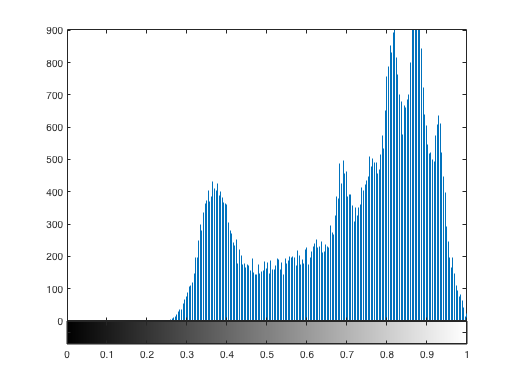

%EXERCICI_3

%apartat a)
img = im2double(imread('image processing/Lab3/lena_color.png'));

%separem els colors
img_red = img(:,:,1);
img_blue = img(:,:,2);
img_green = img(:,:,3);
%Convertim de colors a grisos
img_gray = rgb2gray(img);

%plot dels histogrames
imhist(img_red);

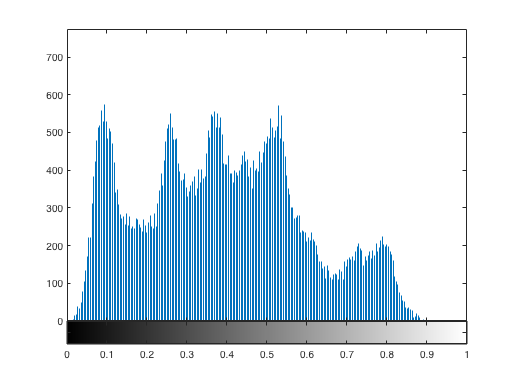

imhist(img_blue);

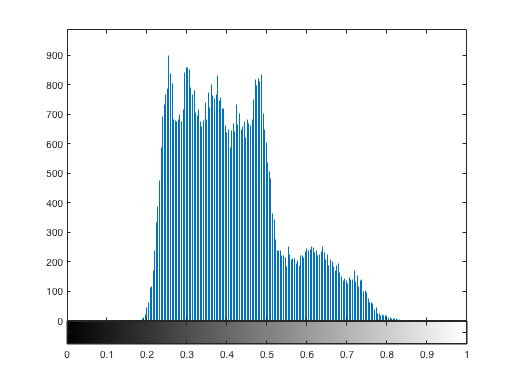

imhist(img_green);

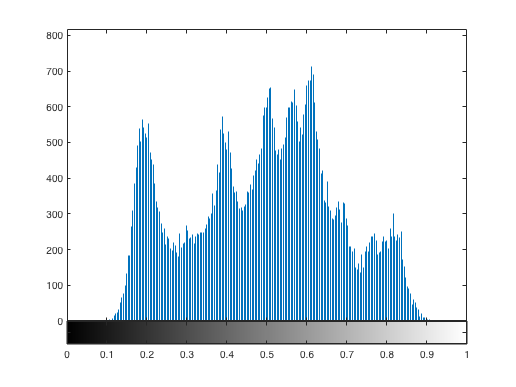

imhist(img_gray);

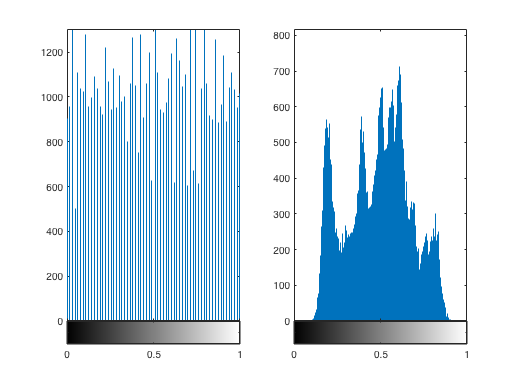


% EQUALIZATION

img1 = im2double(imread('image processing/Lab3/lena_color.png'));
img2 = im2double(imread('image processing/Lab3/gabe_low_contrast.jpg'));
img3 = im2double(imread('image processing/Lab1/Cientefico.jpeg'));

%Covertim les imatges a grisos

img_gray1 = rgb2gray(img1);
img_gray2 = im2gray(img2);
img_gray3 = rgb2gray(img3);

%Equalitzem els histogrames
eq_img1 = histeq(img_gray1);
eq_img2 = histeq(img_gray2);
eq_img3 = histeq(img_gray3);

%Mostrem els nous histogrames i comparem amb els inicials

figure;
subplot(1,2,1);imhist(eq_img1);
subplot(1,2,2);imhist(img_gray1);

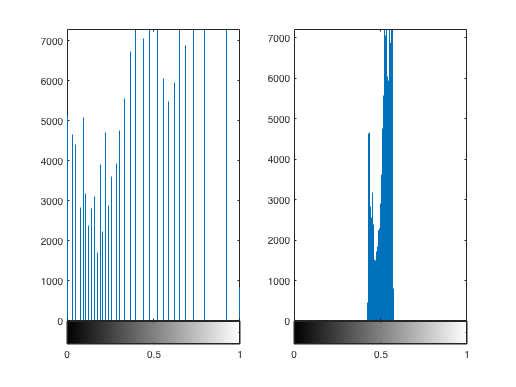


figure;
subplot(1,2,1);imhist(eq_img2);
subplot(1,2,2);imhist(img_gray2)

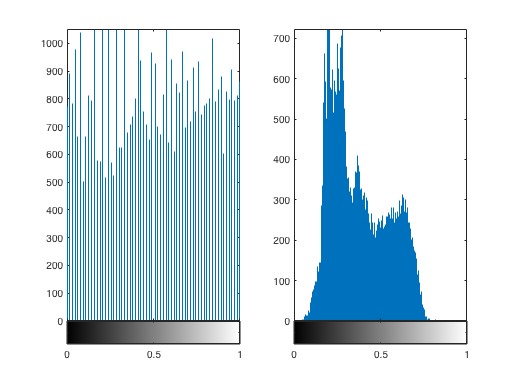


figure;
subplot(1,2,1);imhist(eq_img3);
subplot(1,2,2);imhist(img_gray3)